# Reference Tracking and Disturbance Rejection using MPC: Quadruple Tank Case Study

**Sachin C. Patwardhan*, Anjali P. Deshpande and Sharad Bhartiya* **

(*) Dept. of Chemical Engineering,

 Indian Institute of Technology Bombay, Mumbai 400076 India  

## Introduction 

In the last lesson, we have seen setpoint /reference tracking or servo capabilities of MPC and also it's ability to handle unknown disturbance and/or model-plant mismatch( MPM). In this lesson we will implement the controller on a nonlinear model of Q Tank process. In this exercise, we will see the following capabilities of LMPC-QP controller 

- Disturbance Rejection capability 

- Time varying Set-point tracking capability

- Handling the plant model mismatch that arises due to nonlinearity with added disturbance

**Learning Objectives**

- To understand disturbance rejection and time-varying set point tracking behaviour of Vanilla MPC

- To understand the effect of plant model mismatch that arises due to nonlinearity with disturbance and the measures to overcome

## Closed Loop Simulation using Nonlinear Plant 

With reference to the previous lesson, the main difference here is simulation of the plant dynamics using nonlinear ODE models instead of linear perturbation model. The nonlinear ODE model 

$\frac{d\;X}{\textrm{dt}}=f\left(X,U,D\right)$   ------(1)

simulated over one sampling interval $\textrm{kT}\le t<\left(k+1\right)T$ can be written as 

$X\left(\left(k+1\right)T\right)=X\left(\textrm{kT}\right)+\int_{\textrm{kT}}^{\left(k+1\right)T} f\left(X\left(\tau \right),U\left(\textrm{kT}\right),D\left(\textrm{kT}\right)\right)\;d\tau \equiv F\left(X\left(\textrm{kT}\right),U\left(\textrm{kT}\right),D\left(\textrm{kT}\right)\right)$  ------(2)

 
$$\textrm{where}\;\;\;U\left(\textrm{kT}\right)=u\left(k\right)+U_s \;\;\;\textrm{and}\;D\left(\textrm{kT}\right)=d\left(k\right)+D_s$$


Adopting a notation similar to the linear perturbation model, we can express the nonlinear system evolution as a nonlinear difference equation 

$\;\;\;U\left(k\right)=u\left(k\right)+U_s \;\;\;\textrm{and}\;D\left(k\right)=d\left(k\right)+D_s$ ------(3)

$X\left(k+1\right)=F\left(X\left(k\right),U\left(k\right),D\left(k\right)\right)$  ------(4) 

 $Y\left(k\right)=g\left(X\left(k\right)\right)\;$  ------(5)

Here $F\left(\ldotp ,\ldotp ,\ldotp \right)\;$ some ODE solver such as ode45 in MATLAB. The perturbation state and perturbation output can be found as 

$x\left(k\right)=X\left(k\right)-X_s \;\;\;\textrm{and}\;\;y\left(k\right)=g\left(X\left(k\right)\right)-g\left(X_s \right)$      -----(6) 

When the plant is simulated using equations (3) to (5) and MPC uses the state estimated as 

$\hat{x} \left(k+1\right)=\Phi \hat{x} \left(k\right)+\Gamma u\left(k\right)$   -------(7)

then the model plant mismatch signal 

 $\hat{d} \left(k\right)=y\left(k\right)-\hat{y} \left(k\right)=\left(g\left(X\left(k\right)\right)-g\left(X_s \right)\right)-C\;\hat{x} \left(k\right)\;$ ------(8)

consists of the model plant mismatch (MPM) signal arising from use of linear approximation (7) of discrete nonlinear model (4). Thus, the unknown disturbance rejection feature of MPC is expected to additionally deal with this MPM. 

    In the previous lesson, we did not use the constrained formulation for the target state computations. This is because the simulations did not involve input constraint violations. However, that cannot guaranteed in general and we need to use the constrained formulation for the 

$\min_{u_s \left(k\right)} \left\lbrace {\left(r_f \left(k\right)-y_s \left(k\right)\right)}^T \;W_{\textrm{ys}} \left(r_f \left(k\right)-y_s \left(k\right)\right)\right\rbrace$   ------(9)

subject to,

$y_s \left(k\right)=Gu_s \left(k\right)+{\hat{d} }_f \left(k\right)$ ------(10) 

$u^L \le u_s \left(k\right)\le u^H$ ------ (11)

where $G=C{\left\lbrack I-\Phi \right\rbrack }^{-1} \Gamma_u$ represents the steady state gain matrix.  Note that we can reduce the cost function (9) to the following quadratic cost function 

$\frac{1}{2}\;{\left({\;u}_s \left(k\right)\right)}^T \;H_s \;{\;u}_s \left(k\right)+F_s^T {\;u}_s \left(k\right)$ ------(12)


$$H_s ={2G}^T W_{\textrm{ys}} G\;\;\;\textrm{and}\;\;\;F_s \left(k\right)=-2\;G^T W_{\textrm{ys}} \left(r_f \left(k\right)-{\hat{d} }_f \left(k\right)\right)\;$$


and the constrained optimization problem (9) - (11) reduces to the following QP problem: 

$\min_{u_s \left(k\right)} \;\;\;\frac{1}{2}\;{\left({\;u}_s \left(k\right)\right)}^T \;H_s \;{\;u}_s \left(k\right)+{\left(F_s \left(k\right)\right)}^T {\;u}_s \left(k\right)$--------(13)

subject to 


$$\left\lbrack \begin{array}{c}
I_m \\
{-I}_m 
\end{array}\right\rbrack {\;u}_s \left(k\right)\le \left\lbrack \begin{array}{c}
u_H \\
u_L 
\end{array}\right\rbrack$$


## Target Tracking Control for Quadruple Tank Process

Let us see how this simple target tracking works for the quadruple tank system r represented using a nonlinear ODE model. Let is assume that levels $h_1 \;\textrm{and}\;h_2$ are to be controlled at some desired setpoints. Here we examine the scenario of changing the set-points.  

clear all 
close all

N = 1001 ;      % Simulation run time
global QTank U_k D_k

**Task 1**: Recall that Q Tank process has two steady state operating points. Select the operating point for Q Tank process.  This will load quadruple tank parameters and steady state corresponding to the selected operating point. We can see QTank data structure in workspace.

operating_pt=2;

% Load quadruple tank parameters and steady state 
% The following file loads QTank data structure 
if operating_pt==1
load QTank_MinPhase_Model
else
 load QTank_NonMinPhase_Model 
end

 We then Initialize discrete dynamic model matrices for MPC formulation using the model matrices

% Initialization of linear discrete time model for plant simulation 
phy = QTank.phy ;
gam = QTank.gama_u  ;
gam_d = QTank.gama_d  ;
[n_st,n_ip] = size(gam) ;
C_mat = [ 1 0 0 0 ; 0 1 0 0] ;  % Levels are assume to be directly measured 
[n_op, nx ] = size(C_mat)  ;         
[n_st,n_ip] = size(gam) ;

% Initialization of Internal model for MPC 

mpc.phy = phy ;   
mpc.gam = gam ; 
mpc.C_mat = C_mat ; 
[mpc.n_st,mpc.n_ip] = size(mpc.gam) ;
[mpc.n_op, nx] = size(mpc.C_mat) ; 


**MPC Tuning Parameters**

**Task 2: **Set the prediction horizon n_pred to interval >= 50**.**

mpc.n_pred =50; 

**Task 3:** We have created variables ${\textrm{mpc}\ldotp W}_x$, the **State Weighting Matrix  **and ${\textrm{mpc}\ldotp W}_u$, the **Input Weighting Matrix**.  

 $W_x =\left\lbrack \begin{array}{cccc}
\alpha_1  & 0 & 0 & 0\\
0 & \alpha_2  & 0 & 0\\
0 & 0 & \alpha_3  & 0\\
0 & 0 & 0 & \alpha_4 
\end{array}\right\rbrack$  and  $W_u =\left\lbrack \begin{array}{cc}
\beta_1  & 0\\
0 & \beta_2 
\end{array}\right\rbrack$

alpha(1) =2;  alpha(2) = 10;
alpha(3) =2;  alpha(4) = 2; 
disp('State weighting matrix')
mpc.Wx= diag(alpha );
disp('Input weighting matrix')
beta(1) =2;  beta(2) =1;
mpc.Wu= diag(beta) ;

For the quadruple tank system input voltages are bound between 0 and 5 Volts. Thus, bounds on perturbation inputs, with reference to $U_s ={\left\lbrack \begin{array}{cc}
3 & 3
\end{array}\right\rbrack }^T$can be defined as follows 

$u_H =\left\lbrack \begin{array}{c}
5\\
5
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
3\\
3
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
2\\
2
\end{array}\right\rbrack \;$  and  $u_L =\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
3\\
3
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-3\\
-3
\end{array}\right\rbrack$

We have written a code that  generates matrices needed for specifying input constraints.  

mpc.u_H = [5 5]' - QTank.Us ;  % Physical Input bounds low are 0 and 5 Volts 
mpc.u_L = [0 0]' - QTank.Us ;  % Steady state inputs are [3 3] for nonminimum phase and [3.15 3.15] for non-minimum phase
mpc.deluL = [] ; mpc.deluH = [] ; 

**Generation of  QP matrices**

Note: A function (Gen_QP_Matrices_Tracking) is used to generate QP matrices.

% Generate MPC QP matrices 

[mpc] = Gen_QP_Matrices_Tracking( mpc ) ;
options=optimoptions('quadprog', 'display', 'off');

% Controller related parameters and matrices 

mpc.xkhat = zeros(mpc.n_st,N);
mpc.xs_k = zeros(n_st,N);   % Array to save target states 
mpc.us_k = zeros(n_ip,N) ;  % Array to save target inputs 
mpc.dkhat = zeros(n_op,N); % Model plant mismatch signal 
mpc.dkhat_f = zeros(n_op,N); % Filtered Model plant mismatch signal 
mpc.phy_d = 0.9 * eye(n_op) ;   % Disturbance filter 

% Matrices for target state QP problem 

mpc.Wys = eye(n_op);
mpc.Hs_mat = 2 * mpc.Gain_ss' * mpc.Wys * mpc.Gain_ss ;
mpc.Hs_mat=(mpc.Hs_mat+mpc.Hs_mat')/2;
mpc.Fs_mat =  -2 * mpc.Gain_ss' * mpc.Wys  ; 
mpc.As_mat = [ eye(n_ip) ; -eye(n_ip)]  ;
mpc.bs_vec = [ mpc.u_H ; -mpc.u_L ]; 

% Matrices for simulating system dynamics 

xk = zeros(n_st,N);
uk = zeros(n_ip,N) ;
yk = zeros(n_op,N);
yk(:,1) = C_mat * xk(:,1) ; 
dk = zeros(1,N) ;

rk_f = zeros(n_op,N);  % Setpoint filter parameters 
phy_r = 0.95 * eye(n_op) ; 
rk = [0 0]';

** Disturbance input **

A time varying disturbance input signal is generated such that initially it is set to zero. Then changed from it's initial value to 0.5 ($\left.50<k<600\right)\;$and then subsequently it is changed to -0.25.

for k = 1:N
    if ( k < 50 )
        dk(k) = 0 ;
    elseif (k >= 50 ) && (k < 600)
        dk(k) = 0.5 ;  % Introduce disturbance change at k = 50
    else
        dk(k) = -0.25 ;  % Introduce another disturbance change at k = 250
    end
end

**Closed loop simulations using QP-LMPC under model-plant mismatch **

Optimal controller output is obtained using MATLAB function [quadprog](https://in.mathworks.com/help/optim/ug/quadprog.html). [`x`](https://in.mathworks.com/help/optim/ug/quadprog.html#mw_4fdf75e1-35ab-4c9d-aaf4-c81f677d0f62)` = quadprog(`[`H`](https://in.mathworks.com/help/optim/ug/quadprog.html#bssh6y6-1-H)`,`[`f`](https://in.mathworks.com/help/optim/ug/quadprog.html#d126e155087)`,`[`A`](https://in.mathworks.com/help/optim/ug/quadprog.html#bssh6y6-1_sep_shared-A)`,`[`b`](https://in.mathworks.com/help/optim/ug/quadprog.html#bssh6y6-1_sep_shared-b)`,[],[],[],[],options)` as done in earlier exercises.  Controller calculations at instant k are done assuming state vector is perfectly measured. Quadruple tank Plant Simulation from$k\;\textrm{to}\;k+1$is done using using nonlinear ode model or discrete linear model. Plant model mismatch signal is generated as follows


$$\hat{d} \left(k\right)=y\left(k\right)-C\hat{\mathrm{x}} \left(k\right)$$


This is then filtered using a first order filter 


$$\hat{d_f } \left(k+1\right)=\Phi_d \hat{d_f } \left(k\right)+\left(I-\Phi_d \right)\hat{d} \left(k\right)$$


**Tracking Time Varying Setpoints **

As seen in the previous lesson, a time varying reference input signal is generated such that initially it is set to zero for both the outputs.  Then changed from it's initial value to $r\left(k\right)=\left\lbrack -3\;\;3\ldotp 5\right\rbrack$ in between $250<k<600\;$and then subsequently the vector is changed to $r\left(k\right)=\left\lbrack 3\;\;-4\right\rbrack$. Set point is also filtered as


$$r_f \left(k+1\right)=\Phi_r r_f \left(k\right)+\left(I-\Phi_r \right)r\left(k\right)$$


for k = 1:N-1
    kT(k) = (k-1);

     if ( k < 250 )
        rk = [0 0]'; 
    elseif (k >= 250 ) && (k < 600)
        rk = [-3 3.5 ]' ;  % Introduce another setpoint change at k = 250
     else
          rk = [3 -4 ]' ;
     end
    rk_f(:,k+1) = phy_r * rk_f(:,k) + (eye(n_op) - phy_r) * rk   ; 

    % Controller calculations at instant k 

     % Estimate model plant mismatch and filter it using unity gain filter 
    mpc.dkhat(:,k) = yk(:,k) - mpc.C_mat * mpc.xkhat(:,k) ;  
    mpc.dkhat_f(:,k+1) = mpc.phy_d * mpc.dkhat_f(:,k) + (eye(n_op) - mpc.phy_d) * mpc.dkhat(:,k) ; 

**Computation of Target Inputs and States**

The target inputs and states  are updated at each instant to compensate for the plant model mismatch as follows 


$$u_s \left(k\right)=$$

$$\min_{u_s \left(k\right)} \;\;\;\frac{1}{2}\;{\left({\;u}_s \left(k\right)\right)}^T \;H_s \;{\;u}_s \left(k\right)+{\left(F_s \left(k\right)\right)}^T {\;u}_s \left(k\right)$$


subject to 


$$\left\lbrack \begin{array}{c}
I_m \\
{-I}_m 
\end{array}\right\rbrack {\;u}_s \left(k\right)\le \left\lbrack \begin{array}{c}
u_H \\
u_L 
\end{array}\right\rbrack$$



$$x_s \left(k\right)={\left(I-\Phi \right)}^{-1} \Gamma u_s \left(k\right)$$


These are computed by solving QP problem as above. 

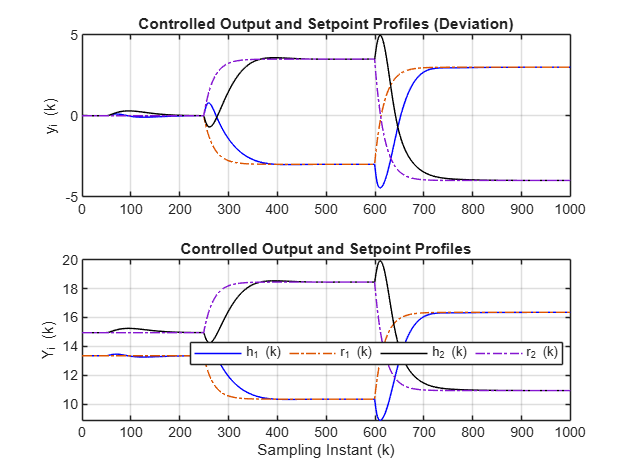

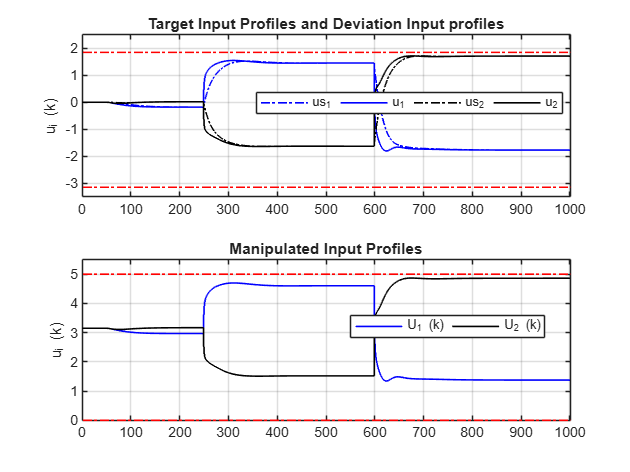

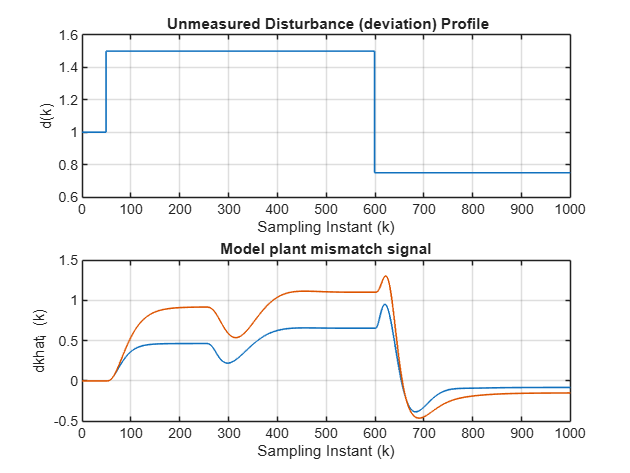

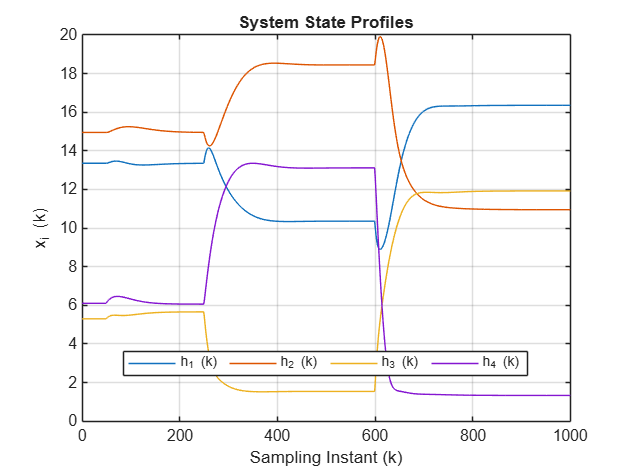

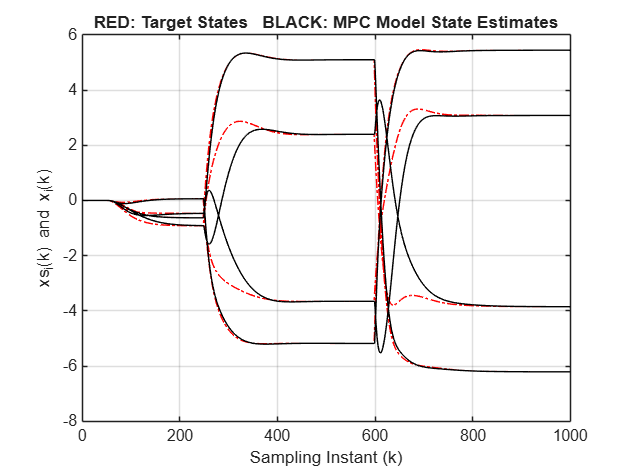

    % Target state computations by solving QP 
    Fsk_vec = mpc.Fs_mat * ( rk_f(:,k+1) - mpc.dkhat_f(:,k+1) ) ; 

    [us_k_QP, fsval] = quadprog(mpc.Hs_mat, Fsk_vec,mpc.As_mat, mpc.bs_vec, [],[],[],[],[], options )  ;
    mpc.us_k(:,k) = us_k_QP ; 
    mpc.xs_k(:,k) = inv(eye(mpc.n_st) - mpc.phy) * mpc.gam * mpc.us_k(:,k) ;

    b_vec = mpc.F_vec ;
    Fk_vec = mpc.F_mat*mpc.xkhat(:,k) - 2 * mpc.WU_mat * mpc.Iu_mat * mpc.us_k(:,k)  - 2 * mpc.Su_mat' * mpc.WX_mat * mpc.Ix_mat * mpc.xs_k(:,k) ;
    [Uf_k,fval] = quadprog(mpc.H_mat, Fk_vec, mpc.A_mat, b_vec,[],[],[],[],[],options )  ;
    mpc.uk = Uf_k(1:n_ip) ;  % Implement only optimal u(k)

    % Internal MPC model update from k to k+1
     mpc.xkhat(:,k+1) = mpc.phy * mpc.xkhat(:,k) + mpc.gam * mpc.uk  ;


 Quadruple tank Plant Simulation from k to k+1 can be done either by using a linear discrete time model or nonlinear ODE model

**Task 4: **Select Plant_Sim as Nonlinear for simulating Q Tank process using a nonlinear ODE model. 

Plant_Sim =0  ; 
     if (Plant_Sim )
         uk(:,k) = mpc.uk ;
         xk(:,k+1) = phy * xk(:,k) + gam * uk(:,k) + gam_d * dk(k)  ;
         yk(:,k+1) = C_mat * xk(:,k+1) ;
     else
         uk(:,k) = mpc.uk ;
         U_k = QTank.Us + mpc.uk ;
         D_k =  QTank.Ds + dk(k)  ;
         [T,Xt] = ode45( 'QTank_Dynamics' , [ 0 QTank.samp_T ], QTank.Xs+xk(:,k)) ;   % Nonlinear plant simulation
         xk(:,k+1) = Xt( end,: )' - QTank.Xs ;
         yk(:,k+1) = C_mat * xk(:,k+1) ;
     end

 end
uk(:,N) = uk(:,N-1) ;
kT(N) = N-1 ;
mpc.dkhat(:,N) = mpc.dkhat(:,N-1) ; 
mpc.us_k(:,N) = mpc.us_k(:,N-1) ;
mpc.xs_k(:,N) = mpc.xs_k(:,N-1)  ; 

** Display Simulation Results **

Observe the figures below for state profiles tracking control, time varying set-point tracking control for outputs, inputs, model plant mismatch signal, Unmeasured disturbance input, Target State Profiles and Target Input Profiles.

Set_Graphics_Parameters 
Xk = QTank.Xs + xk ;   Uk = QTank.Us + uk ; Dk = QTank.Ds + dk ;
Yk = yk + C_mat * QTank.Xs ;  Rk_f = rk_f + C_mat * QTank.Xs ;
u_limit = [mpc.u_L(1)*ones(N,1) mpc.u_H(1)*ones(N,1)]  ;

% Controlled output profiles 
figure, subplot(211), 
plot(kT, yk(1,:), 'b',  kT, rk_f(1,:), '-.', kT, yk(2,:), 'k', kT, rk_f(2,:), '-.'), grid
title('Controlled Output and Setpoint Profiles (Deviation)'), ylabel('y_i (k)')
subplot(212), plot(kT, Yk(1,:), 'b',  kT, Rk_f(1,:), '-.', kT, Yk(2,:), 'k', kT, Rk_f(2,:), '-.'), grid
xlabel('Sampling Instant (k)'), ylabel('Y_i (k)')
legend('h_1 (k)', 'r_1 (k)', 'h_2 (k)', 'r_2 (k)', 'Orientation','horizontal','Location','Best')
title('Controlled Output and Setpoint Profiles')

%Manipulated input profiles
figure, subplot(211), stairs(kT, mpc.us_k(1,:)', '-.b','LineWidth',1), grid
hold on
stairs(kT, uk(1,:)', 'b','LineWidth',1)
stairs(kT, mpc.us_k(2,:)', '-.k','LineWidth',1)
stairs(kT, uk(2,:)', 'k','LineWidth',1)
stairs(u_limit, '-.r', 'LineWidth',1)
axis([0 N -3.5 2.5])
hold off
ylabel('u_i (k)'), title('Target Input Profiles and Deviation Input profiles')
legend( 'us_1', 'u_1', 'us_2', 'u_2', 'Orientation','horizontal','Location','Best')
subplot(212), stairs(kT, Uk(1,:)', 'b','LineWidth',1),  grid
hold on, stairs(kT, Uk(2,:)', 'k','LineWidth',1),
stairs(u_limit+QTank.Us', '-.r', 'LineWidth',1), hold off
axis([0 N 0 5.5]), ylabel('u_i (k)')
title('Manipulated Input Profiles')
legend( 'U_1 (k)', 'U_2 (k)','Orientation','horizontal','Location','Best')

% Disturbance input and Model Plant Mismatch profiles 
figure, subplot(211), stairs( kT, Dk,'LineWidth',1 ), grid
xlabel('Sampling Instant (k)'), ylabel('d(k)')
title(' Unmeasured Disturbance (deviation) Profile')
subplot(212), stairs( kT, mpc.dkhat_f','LineWidth',1 ), grid
xlabel('Sampling Instant (k)'), ylabel('dkhat_i (k)')
title('Model plant mismatch signal')

% System State profiles and MPC internal model profiles  
figure, plot(kT, Xk(1,:), kT, Xk(2,:), kT, Xk(3,:), kT, Xk(4,:)), grid
xlabel('Sampling Instant (k)'), ylabel('x_i (k)')
legend('h_1 (k)', 'h_2 (k)', 'h_3 (k)', 'h_4 (k)', 'Orientation','horizontal','Location','Best')
title('System State Profiles')
figure, plot(kT, mpc.xs_k, '-.r', kT, mpc.xkhat, 'k'), grid
title('RED: Target States   BLACK: MPC Model State Estimates')
xlabel('Sampling Instant (k)'), ylabel('xs_i(k) and x_i(k)')



**Task 5: **Go to Task 2 and try changing the prediction horizon. Observe the effect on servo response by increasing or decreasing the prediction horizon. 

**Task 6: **Go to Task 3 and try changing the weighting matrices. How does the response change if all weights in $W_x$ are equal? What happens if only one weight in $W_x$ is say 100 times higher than the rest three?  What do you observe when input weights in $W_u$ are unequal? 

**Task 7:** You can try above mentioned tasks by changing the plant simulation to linear model in Task 4.

**Task 8:** Now change the operating point and again observe the results.

## Conclusion

Thus we can see that the tracking control established using linear discrete time model works well with nonlinear process model. It rejects the disturbance and also tracks the time varying setpoint trajectory. Plant model mismatch that arises due to nonlinearity with disturbance is taken care of by generating plant model mismatch signal, from measurement signal and the states for mpc. 